To create a metric graph, one just needs to input the number of vertices of the graph. 

The following block creates a test example.

myGraph = MetricGraph(8) % Defines a metric graph with 8 vertices.

myGraph =   MetricGraph with properties:

    incidenceMatrix: [8×0 double]
            lengths: [1×0 double]


Then to add an edge one needs to precise the starting vertex of the edge, its ending vertex and the length of the edge.

Be aware that certain functions do not work with multigraphs, so one may need to choose to represent a given metric graph with more vertices to make sure that there are no multiple edges.

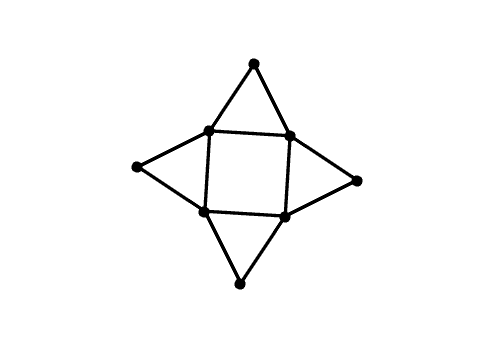

myGraph.addEdge(1,2,4) % Adds an edge on myGraph from vertex 1 to vertex 2. This edge has length 4.
myGraph.addEdge(1,3,4)
myGraph.addEdge(2,3,4)
myGraph.addEdge(2,4,4)
myGraph.addEdge(2,5,4)
myGraph.addEdge(3,6,4)
myGraph.addEdge(3,7,4)
myGraph.addEdge(4,5,4)
myGraph.addEdge(5,6,4)
myGraph.addEdge(5,8,4)
myGraph.addEdge(6,7,4)
myGraph.addEdge(6,8,4)

% This is a way to plot myGraph. It allows to
% modify manually the coordinates of the vertices.
[X, Y] = myGraph.getLaplacianCoordinates;
myGraph.plot(X, Y) 

If one does not care about handling the coordinates of the vertices of a graph, the following will plot **myGraph** in a shorter way.

myGraph.plot

To create a divisor, one only needs to input the metric graph the divisor is defined on.

myDivisor = Divisor(myGraph)

myDivisor =   Divisor with properties:

    edgeIndexVector: [1×0 double]
     distanceVector: [2×0 double]
       degreeVector: [1×0 double]


The way to describe a precise point of a graph is to give first the index of the edge the point lies on (where the n-th edge is the n-th edge added to the graph) and then give the distance from the start of the edge to the point.

To increase the value of a divisor at a point, one needs to first precise the point where the value is increased and then specify the amount that one wants to add.

The following line of code adds a chip of degree 1 on the edge number 2, at distance 3 from the start of this edge (and so at distance 1 from its end).

myDivisor.addChip(2,3,1)

Once can plot this example divisors just like graphs.

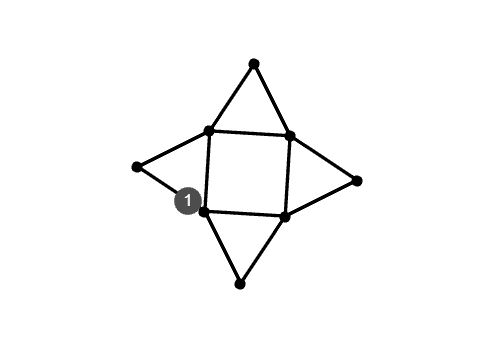

myDivisor.plot

Then we make **myDivisor** into a less trivial divisor.

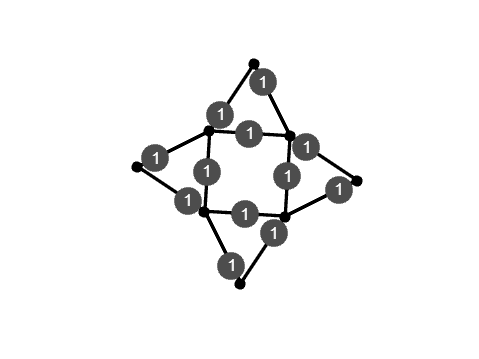

myDivisor.addChip(1,1,1)
myDivisor.addChip(3,2,1)
myDivisor.addChip(4,1,1)
myDivisor.addChip(5,2,1)
myDivisor.addChip(6,2,1)
myDivisor.addChip(7,3,1)
myDivisor.addChip(8,1,1)
myDivisor.addChip(9,2,1)
myDivisor.addChip(10,1,1)
myDivisor.addChip(11,1,1)
myDivisor.addChip(12,3,1)
myDivisor.plot

We now want to see what is the result when we apply Dhar's algorithm on **myDivisor** if the chosen point is the beginning point of the first edge.

First we clone the divisor to be able to compare the divisor with the corrensponding reduced divisor and then we ask to compute this reduced divisor.

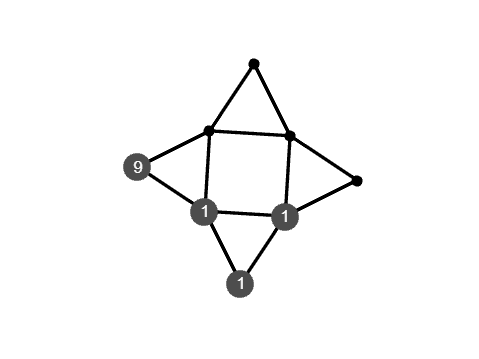

copy = myDivisor.clone;
copy.dharEffective(1, 0, X, Y)

% Clone.dharEffective(1, 0) does the same work
% except it does not produce the plot.

Just to check that Dhar's algorithm runs properly, let us see that the output of the algorithm is equivalent (ie the same element in the Picard group) to the divisor we started with.

display(areEquivalent(myDivisor, copy))

  logical

   1



Be aware that the method *areEquivalent *checks if a given solution of a linear system is a vector of integers. This may output wrong answers in the case of two divisors that are close to being equivalent, due to rounding errors.

We can also illustrate the fact that Dhar's algorithm will output a divisor with a smaller euclidean norm.

First we create the divisor that we need to substract to both **myDivisor** and **copy.**

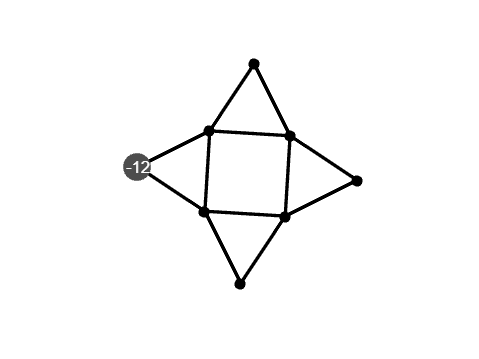

pointToSubstract = Divisor(myGraph);
pointToSubstract.addChip(1,0,12)
% The next line will multiply the degree
% of the divisor by -1
pointToSubstract.scalarMultiplication(-1)
plot(pointToSubstract)

Then in second we add this divisor to both **myDivisor** and **copy**, before computing the euclidean norm.

myDivisor = addition(myDivisor, pointToSubstract);
fprintf('The euclidean norm of myDivisor is %d.\n', pNorm(myDivisor))

The euclidean norm of myDivisor is 1.749286e+01.


copy = addition(copy, pointToSubstract);
fprintf('The euclidean norm of copy is %d.', pNorm(copy));

The euclidean norm of copy is 5.099020e+00.

Let us now see an example of a double covering. First we define a new graph that will serve as the base space of our double covering.

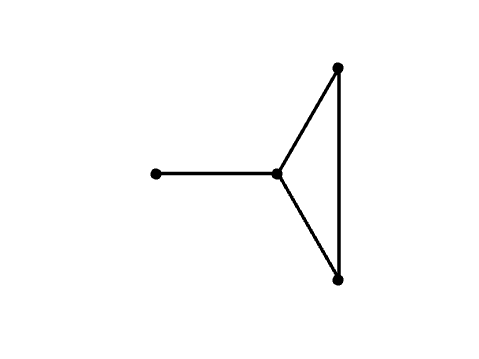

baseGraph = MetricGraph(4);
baseGraph.addEdge(1,2,1)
baseGraph.addEdge(2,3,1)
baseGraph.addEdge(3,1,1)
baseGraph.addEdge(1,4,1)
baseGraph.plot

We now define a double covering of **baseGraph. **We need to precise that it is the base graph and we will have created the trivial covering of the base graph, then decide which edges we want to go from a fiber of the double covering to the other.

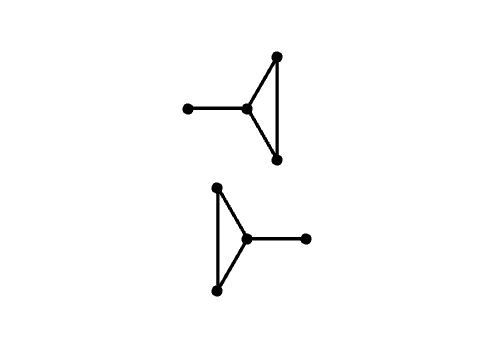

myCovering = DoubleCovering(baseGraph);
myCovering.plot % Hitherto two copies of baseGraph

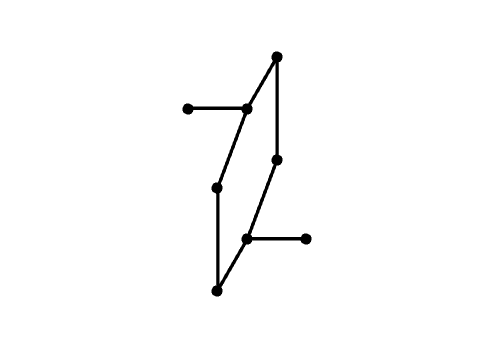

myCovering.makeEdgeCross(3)
myCovering.plot % Now it is interesting

Let us see an example of an antisymmetric divisor on **myCovering**.

myAntiDivisor = AntiSymDivisor(myCovering);

To modify this divisor, one will specify the degree to add at a position and it will automatically be made antisymmetric.

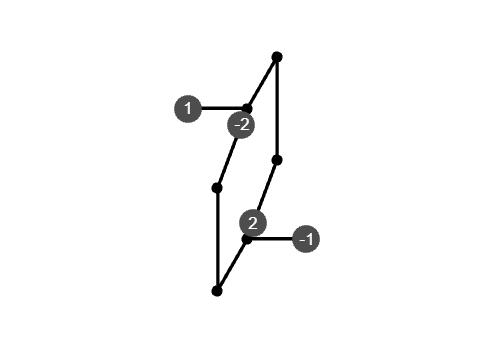

myAntiDivisor.addChip(3,0.8,2)
myAntiDivisor.addChip(8,1,-1)
myAntiDivisor.plot